Plotting

x = [1 2 3 4 5 6];
y = [3 4 5 6 7 8];
x2 = [ 4 5 6 6 7]

x2 =      4     5     6     6     7


y2 = [3 4 5 6 7]

y2 =      3     4     5     6     7


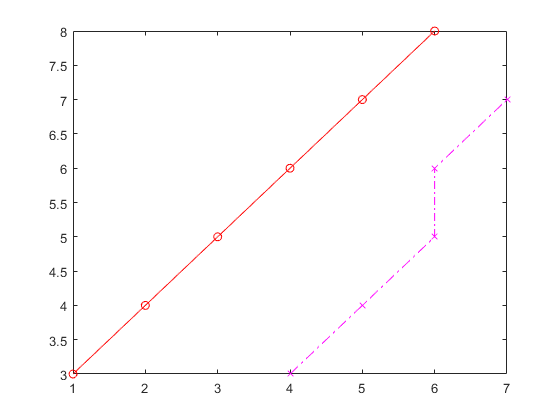

% plot(x1, y1, style1, x2, y2, style2,...)
plot(x,y, 'or-', x2, y2, 'mx-.')

Subplot

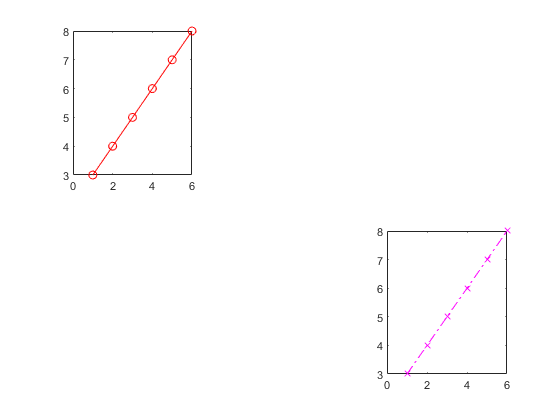

x = [1 2 3 4 5 6];
y = [3 4 5 6 7 8];
% everything under each subplot call will be plotted to that subplot
subplot(2,3,1)
plot(x,y, 'or-')
subplot(2,3,6)
plot(x,y,'mx-.')

Hold Function 

figure
x = [1 2 3 4 5 6];
y = [3 4 5 6 7 8];
plot(x,y)
% allows you to plot multiple data sets in the same figure without putting
% them in the same plot() function
hold on
plot(x2, y2)
hold off


Labeling

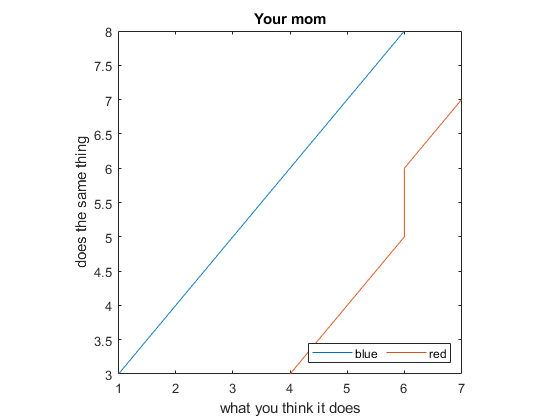

% Set the axes (we'll tell you which one to use)
% axis ([minX, maxX, minY, maxY])
% axis equal
axis square

% Labeling title, x and y labels, and legend
title('Your mom')
xlabel('what you think it does')
ylabel('does the same thing')
legend('blue', 'red', 'location', 'southeast', 'numcolumns', 2)

% legend(label1, label2, ..., 'location', cardinal direction, 'numcolumns',
% numOfColsYouWant)
    % Location and numcolumns are optional, but you have to have enough
    % labels to match each of your data sets

Plotting a Circle

figure
r = 5;
th = linspace(0, 2*pi);
x = r.*cos(th) + 2 % --> +/- center shift

x =     7.0000    6.9899    6.9598    6.9096    6.8397    6.7504    6.6418    6.5146    6.3692    6.2063    6.0264    5.8302    5.6187    5.3925    5.1528    4.9003    4.6361    4.3614    4.0771    3.7844    3.4846    3.1788    2.8682    2.5542    2.2379    1.9207    1.6038    1.2884    0.9760    0.6676    0.3647    0.0683   -0.2203   -0.5000   -0.7696   -1.0280   -1.2743   -1.5074   -1.7263   -1.9303   -2.1184   -2.2899   -2.4442   -2.5805   -2.6985   -2.7975   -2.8771   -2.9372   -2.9774   -2.9975


y = r.*sin(th) + 4

y =     4.0000    4.3171    4.6330    4.9463    5.2557    5.5602    5.8583    6.1490    6.4310    6.7032    6.9645    7.2139    7.4504    7.6730    7.8807    8.0729    8.2486    8.4073    8.5482    8.6707    8.7745    8.8591    8.9240    8.9692    8.9943    8.9994    8.9843    8.9491    8.8940    8.8192    8.7250    8.6118    8.4800    8.3301    8.1628    7.9788    7.7787    7.5635    7.3338    7.0908    6.8353    6.5684    6.2911    6.0047    5.7101    5.4087    5.1016    4.7900    4.4753    4.1586


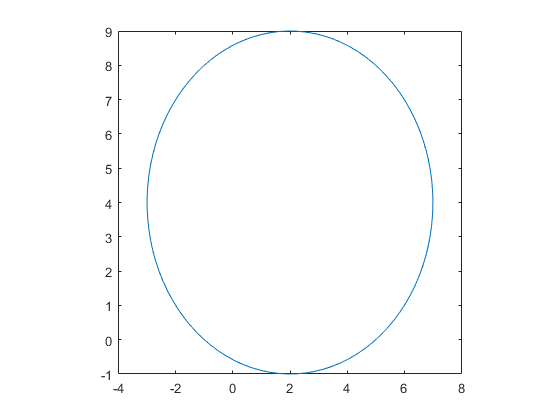

plot(x,y)
axis square

    % That's it - every time

Plotting a Square

figure
x = [2, 2, -2, -2, 2]

x =      2     2    -2    -2     2


y = [2, -2, -2, 2, 2]

y =      2    -2    -2     2     2


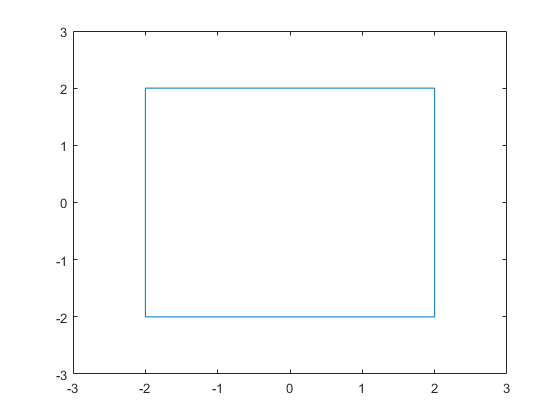

    % make sure you have 5 points to close the square!
plot(x,y)
axis([-3, 3, -3, 3])

Numerical Methods:

Interpolation and extrapolation

figure
x = [ 1 3 5 8]

x =      1     3     5     8


y = [1 9 25 64]

y =      1     9    25    64


% Linear interp
newX = [2 4 6 7]

newX =      2     4     6     7


newY = interp1(x, y, newX)

newY =      5    17    38    51


% Cubic interp
newY = spline(x, y, newX)

newY =     4.0000   16.0000   36.0000   49.0000



% Cubic extrap
newX = [0 10]

newX =      0    10


newY = spline(x,y,newX)

newY =    -0.0000  100.0000


newY = interp1(x, y, newX, 'spline')

newY =          0  100.0000


% Linear extrap
newY = interp1(x, y, newX, [],'extrap')

newY =     -3    90


Curve fitting

x = [ 1 3 5 8]

x =      1     3     5     8


y = [1 8 17 69]

y =      1     8    17    69


order = 3

order = 3

houbf = length(x)-1 % special order we tell you to use

houbf = 3

coeffs = polyfit(x, y, order)

coeffs =     0.3310   -2.7286   10.1119   -6.7143


fitX = linspace(min(x), max(x))

fitX =     1.0000    1.0707    1.1414    1.2121    1.2828    1.3535    1.4242    1.4949    1.5657    1.6364    1.7071    1.7778    1.8485    1.9192    1.9899    2.0606    2.1313    2.2020    2.2727    2.3434    2.4141    2.4848    2.5556    2.6263    2.6970    2.7677    2.8384    2.9091    2.9798    3.0505    3.1212    3.1919    3.2626    3.3333    3.4040    3.4747    3.5455    3.6162    3.6869    3.7576    3.8283    3.8990    3.9697    4.0404    4.1111    4.1818    4.2525    4.3232    4.3939    4.4646


fitY = polyval(coeffs, fitX)

fitY =     1.0000    1.3908    1.7649    2.1230    2.4660    2.7943    3.1088    3.4102    3.6991    3.9763    4.2425    4.4983    4.7445    4.9817    5.2108    5.4323    5.6469    5.8555    6.0586    6.2570    6.4514    6.6425    6.8309    7.0175    7.2028    7.3876    7.5726    7.7585    7.9460    8.1358    8.3286    8.5252    8.7261    8.9321    9.1439    9.3623    9.5878    9.8213   10.0634   10.3148   10.5762   10.8484   11.1319   11.4276   11.7362   12.0582   12.3945   12.7457   13.1126   13.4958


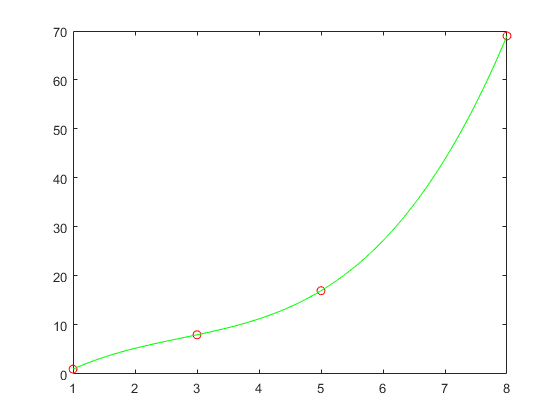

    % that's it - just write these lines to curve fit
plot(x, y, 'ro', fitX, fitY, 'g')

Calculus!!

% Numerical
x = [1 2 3 4]

x =      1     2     3     4


y = [1 4 9 16]

y =      1     4     9    16


    % Derivative
    yDiff = diff(y)

yDiff =      3     5     7


    deriv = diff(y) ./ diff(x)

deriv =      3     5     7


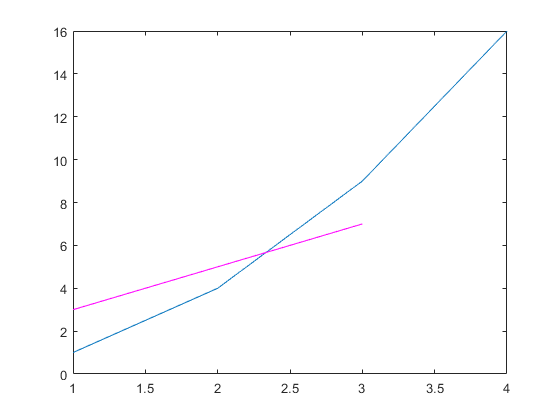

    %diff() will always be 1 less than length of x
    plot(x, y)
    hold on
    plot(x(1:end-1), deriv, 'm') 

        % we'll tell you to leave of the last x or the first one
    
    % Integral
    x = [1 2 3]

x =      1     2     3


    y = [10 20 30]

y =     10    20    30


    int = cumtrapz(x, y)

int =      0    15    40


        % cumulative trapezoidal sum
    int2 = cumsum(y)
        % cumulative sum - and it assumes the x values increase by 1 (x =
        % 1:length(y)

% Analytical
coeffs = [3 5 3]

coeffs =      3     5     3


    % Derivative
    deriv = polyder(coeffs)

deriv =      6     5


    % Integral
    integ = polyint(coeffs)

integ =     1.0000    2.5000    3.0000         0




% Note: the numerical derivative/integral will give you a vector of the
% y-values for that derivative or integral i.e. you can plot them directly

% The analytical derivative/integral will give you the coefficients of the
% derivative/integral - you can not plot that directly: you will have to
% use the lines below to plot
    newX = linspace(min(x), max(x))
    newY = polyval(coeffs, newX)

